clear
clc

num = [4]

num = 4

den = [2 1]

den =      2     1


G = tf(num, den)

G =
 
     4
  -------
  2 s + 1
 
Continuous-time transfer function.



T_d = 1;
G_d = c2d(G,T_d,'zoh')

G_d =
 
    1.574
  ----------
  z - 0.6065
 
Sample time: 1 seconds
Discrete-time transfer function.



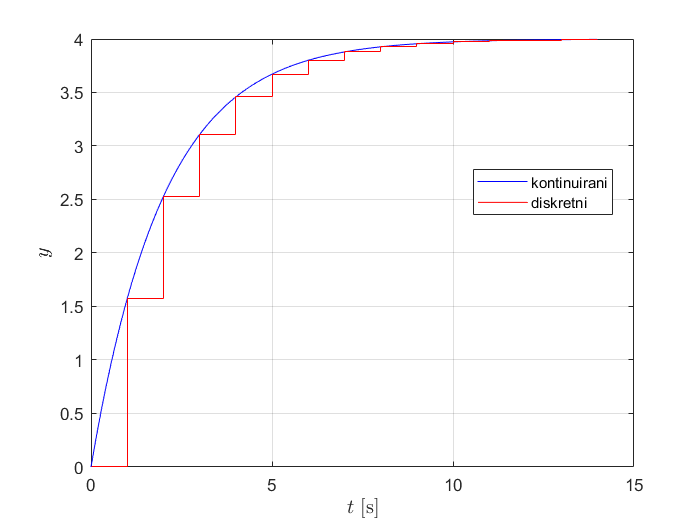


[num_d,den_d] = tfdata(G_d,'v');

% početni uvjeti
y_p1 = 0;
u_p1 = 0;

% broj točaka i priprema vektora za crtanje rezultata
N = 6;
y_d = zeros(N,1);
t_d = zeros(N,1);
u = 1;

for i = 1:N
    % rekurzivna relacija:
    y = 0.6065*y_p1 + 1.574*u_p1;
    % osvjezavanje vrijednosti u proslim koracima
    y_p1 = y;
    u_p1 = u;
    % punjenje vektora za crtanje rezultata
    y_d(i) = y;
    t_d(i) = (i-1)*T_d;
end

[y_k,t_k] = step(G,(N-1)*T_d);
plot(t_k,y_k*u,'b')
grid on
hold on
stairs(t_d,y_d,'r')
hold off
xlabel('$t$ [s]','interpreter','latex','fontsize',12)
ylabel('$y$','interpreter','latex','fontsize',12)
legend('kontinuirani','diskretni','location','best')